# This code is based on methods in J. Reidl et al. 2007 and discussions between Chi and Hiroshi

This code uses function subaxis and JadeR (Cardoso, 2013) Overall this code should do a good job. Foe cortex-wide imaging of GC6s signal from excitatory neurons, first 40 PCA modes are retained to do ICA further. Farewell 2015.

## Set Initials and Animals and epochs

Events = {'temp'}; % {'CueAligned', 'MovOnsetAligned','RewardAligned'}; % need to be modified
% Currently does not support per-Event analysis.
Initial = 'KM'; 
Animals = {'tlx49'}; 
Date = '231126';
signal = 'df_f'; % 'df_f' or 'raw'
working_directory = '/home/naohiro/Desktop/Yoshida_analysis/Wide-field-calcium-imaging/';

close all
clc

## Main Body

disp('Running ICA for all sessions...');

Running ICA for all sessions...


Running KM_231126_tlx49_df_f_all_reg.mat...


Elapsed time is 3.445129 seconds.


Spatial Kurtosis: 4.8827+/-1.6964


Temporal Kurtosis: 3.547+/-1.7824


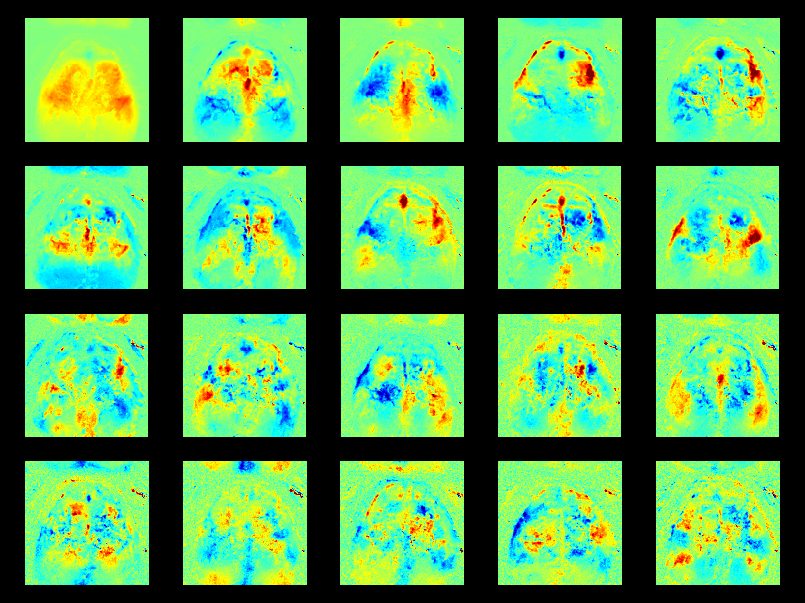

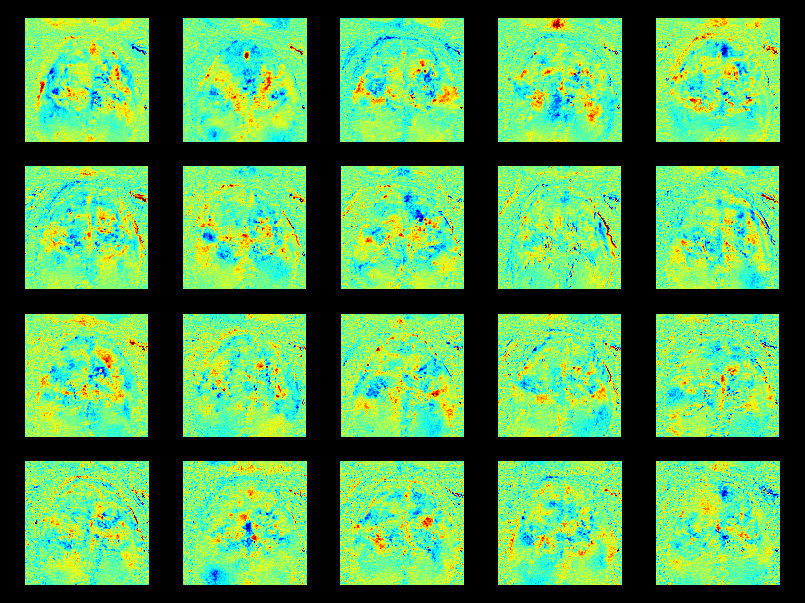

jade -> Looking for 40 sources
jade -> Removing the mean value
jade -> Whitening the data
jade -> Estimating cumulant matrices
jade -> Contrast optimization by joint diagonalization
jade -> Sweep #  0 completed in 780 rotations
jade -> Sweep #  1 completed in 780 rotations
jade -> Sweep #  2 completed in 780 rotations
jade -> Sweep #  3 completed in 780 rotations
jade -> Sweep #  4 completed in 780 rotations
jade -> Sweep #  5 completed in 775 rotations
jade -> Sweep #  6 completed in 768 rotations
jade -> Sweep #  7 completed in 761 rotations
jade -> Sweep #  8 completed in 759 rotations
jade -> Sweep #  9 completed in 758 rotations
jade -> Sweep # 10 completed in 753 rotations
jade -> Sweep # 11 completed in 752 rotations
jade -> Sweep # 12 completed in 744 rotations
jade -> Sweep # 13 completed in 741 rotations
jade -> Sweep # 14 completed in 744 rotations
jade -> Sweep # 15 completed in 743 rotations
jade -> Sweep # 16 completed in 733 rotations
jade -> Sweep # 17 completed in 733 

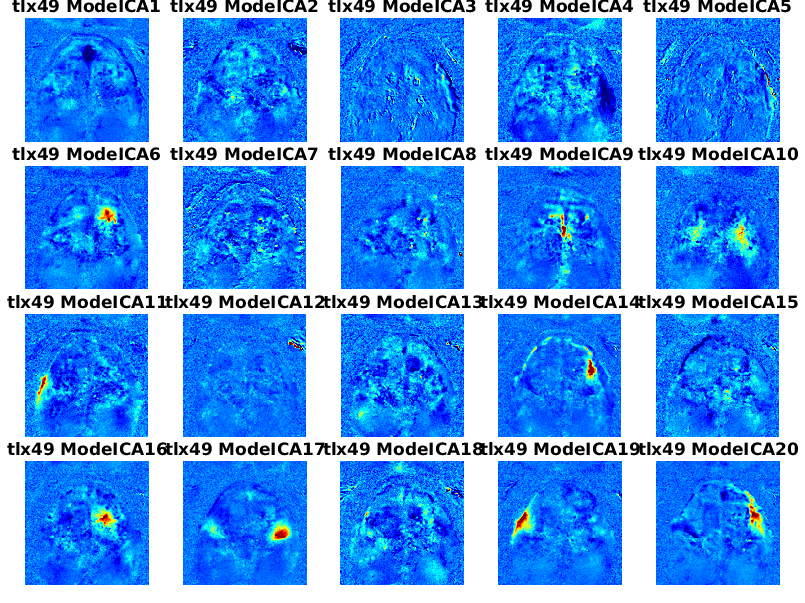

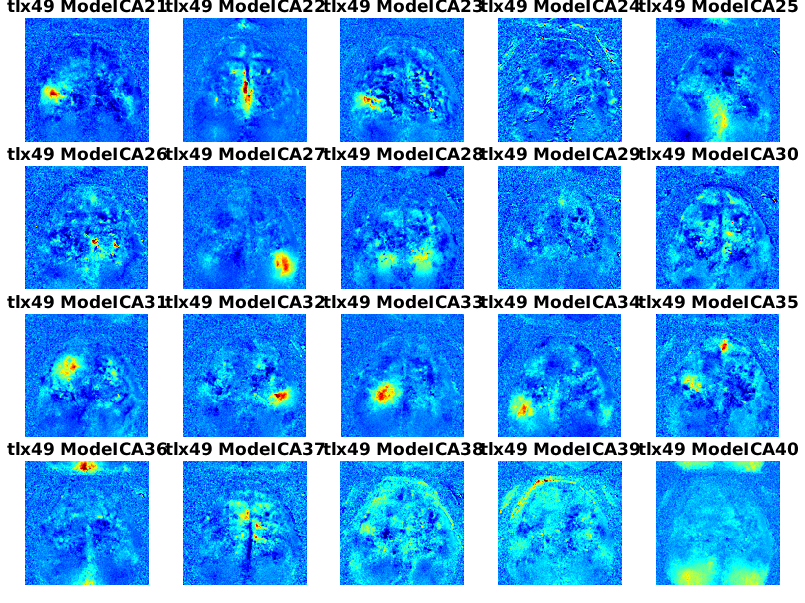

Saving...


Finish KM_tlx49


for curr_animal = 1:length(Animals)
    
    clearvars -except Initial IN Animals Events curr_animal working_directory Date signal
    Animal = Animals{curr_animal};
    
    Temporal_Mean_allsession = [];
    AllPixel_allsession = [];
    
    for curr_event = 1:length(Events)
        
        Event = Events{curr_event};
        
        % Data folder
        cd([working_directory Date filesep Initial '_' Animal filesep]);
        All_file_list = dir(cd);
        if strcmp(signal, 'df_f')
            Image_file_list = {All_file_list(cellfun(@(x) ~isempty(strfind(x,'df_f_all_reg')), {All_file_list.name})).name}; 
        elseif strcmp(signal, 'raw')
            Image_file_list = {All_file_list(cellfun(@(x) ~isempty(strfind(x,'downsamp_im_all_reg')), {All_file_list.name})).name}; 
        end
        
        FrameNumPerSession.(Event) = nan(size(Image_file_list));
        
        % Load data session by session
        Im_Session = length(Image_file_list);
        
        for curr_session = 1:length(Image_file_list)
            tic % time it
            cd([working_directory  Date filesep Initial '_' Animal filesep])  
            disp(['Running ' Image_file_list{curr_session} '...'])
            
            % Load image
            load(Image_file_list{curr_session}, '-mat');
            % two dimensions of pixels and time series are assumed
            % AlignedIm_Cue, AlignedIm_MovOnset and
            % AlignedIm_Reward are put in this mat file
            if strcmp(signal, 'df_f')           
                totalBlock = length(df_f_all_reg);  
            elseif strcmp(signal, 'raw')            
                totalBlock = length(downsamp_im_all_reg);  
            end
            % Get the temporal mean of the data for reconstruction, record
            % pixel number for reconstruction
            for i_block = 1:totalBlock
                ValidPixel = [];
                if ~isempty(strfind(Event,'Cue'))
                    ValidPixel = AlignedIm_Cue.Cue_Conc;
                    FrameNumPerSession.(Event)(curr_session) = size(AlignedIm_Cue.Cue_Conc,2);
                elseif ~isempty(strfind(Event,'MovOnset'))
                    ValidPixel = AlignedIm_MovOnset.MovOnset_Conc;
                    FrameNumPerSession.(Event)(curr_session) = size(AlignedIm_MovOnset.MovOnset_Conc,2);
                elseif ~isempty(strfind(Event,'Reward'))
                    ValidPixel = AlignedIm_Reward.Reward_Conc;
                    FrameNumPerSession.(Event)(curr_session) = size(AlignedIm_Reward.Reward_Conc,2);
                elseif strcmp(signal, 'df_f') 
                    ValidPixel = df_f_all_reg{i_block};
                    FrameNumPerSession.(Event)(curr_session) = size(df_f_all_reg{i_block},2);
                elseif strcmp(signal, 'raw') 
                    ValidPixel = downsamp_im_all_reg{i_block};
                    FrameNumPerSession.(Event)(curr_session) = size(downsamp_im_all_reg{i_block},2);
                end
                
                AllPixel_allsession = horzcat(AllPixel_allsession, ValidPixel);
            end
            toc
        end
    end
    
    Temporal_Mean_allsession = mean(AllPixel_allsession,2); % Temporal mean
    
    % Check the kurtosis for all concataneted frames
    Kur_S = kurtosis(AllPixel_allsession);
    Kur_T = kurtosis(AllPixel_allsession');
    
    disp(['Spatial Kurtosis: ' num2str(nanmean(Kur_S)) '+/-' num2str(nanstd(Kur_S))]);
    disp(['Temporal Kurtosis: ' num2str(nanmean(Kur_T)) '+/-' num2str(nanstd(Kur_T))]);
    
    % ######################################## PCA ########################################
    [COEFF_all,SCORE_all,latent_all] = pca(AllPixel_allsession'); % SCORE: Column: Component, Row: Frame
    Info = cumsum(latent_all)./sum(latent_all); % Fraction of variance explained
    CompNum = 40; % Choose first 40 componnets
    cd([working_directory  Date filesep Initial '_' Animal filesep])  ;
    mkdir('ICA');
    cd('ICA');
    % Save PCA so we can start from here next time if using different numbers of
    % PCs for ICA
    save([Initial '_' Animal '_PCA'],'COEFF_all','SCORE_all','latent_all','-v7.3');
    
    ModePCA = COEFF_all(:,1:CompNum); % COEFF: Row: Pixel, Column: Component
    
    % Plot
    cd([working_directory  Date filesep Initial '_' Animal filesep 'ICA'])  ;
    mkdir(['ICA_' num2str(CompNum)]); cd(['ICA_' num2str(CompNum)]);
    addpath([working_directory 'PCA_and_ICA' filesep 'Subaxis']);
    
    figure
    set(gcf,'color','k')
    for mode = 1:20
        subaxis(4,5,mode, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.03);
        clims = [-0.04 0.04];
        image = ModePCA(:,mode);
        imagesc(reshape(image,[128 128]),clims)
        colormap jet;
        axis square
        axis off
        title([Animal ' ModePCA' num2str(mode)]);
    end
    saveas(gcf,[Animal '_ModePCA_1-20.fig']);
%     close all
    
    figure
    set(gcf,'color','k')
    for mode = 21:40
        subaxis(4,5,mode-20, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.03);
        clims = [-0.04 0.04];
        image = ModePCA(:,mode);
        imagesc(reshape(image,[128 128]),clims)
        colormap jet;
        axis square
        axis off
        title([Animal ' ModePCA' num2str(mode)]);
    end
    saveas(gcf,[Animal '_ModePCA_21-40.fig']);
%     close all
    
    if CompNum >= 60
        figure
        set(gcf,'color','k')
        for mode = 41:60
            subaxis(4,5,mode-40, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.03);
            clims = [-0.04 0.04];
            image = ModePCA(:,mode);
            imagesc(reshape(image,[128 128]),clims);
            colormap jet;
            axis square
            axis off
            title([Animal ' ModePCA' num2str(mode)]);
        end
        saveas(gcf,[Animal '_ModePCA_41-60.fig']);
        close all
    end
    
    if CompNum >= 80
        figure
        set(gcf,'color','k')
        for mode = 61:80
            subaxis(4,5,mode-60, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.03);
            clims = [-0.04 0.04];
            image = ModePCA(:,mode);
            imagesc(reshape(image,[128 128]),clims);
            colormap jet;
            axis square
            axis off
            title([Animal ' ModePCA' num2str(mode)]);
        end
        saveas(gcf,[Animal '_ModePCA_61-80.fig']);
        close all
    end
    
    if CompNum >= 100
        figure
        set(gcf,'color','k')
        for mode = 81:100
            subaxis(4,5,mode-80, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.03);
            clims = [-0.04 0.04];
            image = ModePCA(:,mode);
            imagesc(reshape(image,[128 128]),clims);
            colormap jet;
            axis square
            axis off
            title([Animal ' ModePCA' num2str(mode)]);
        end
        saveas(gcf,[Animal '_ModePCA_81-100.fig']);
        close all
    end
    
    % ######################################## ICA ########################################
    % ICA algorithm: JADE, Cardoso, 2013, entropy
    addpath([working_directory 'PCA_and_ICA' filesep 'JADER']); 
    ModeICA = [];
    SCORE_ICA_all = [];
    B = jadeR(ModePCA'); % Input: Row: Mode, Column: Pixel; Get: B: Row: Independent Component(IC), Column: Component from PCA;
    ModeICA = (B*ModePCA')'; % Get: ModeICA: Column: Independent Component(IC), Row: Pixel;
    % Get temporal trace of each ICA mode
    A = inv(B)'; % column: PCA, row: IC, each column: PCA project on IC;
    SCORE_ICA_all = A*SCORE_all(:,1:CompNum)'; % Raw: ICA Component, Column: Frame
    
    % Saving
%     cd(['Z:\Data\' Initial '_' Animal filesep 'EventAligned_Gap500\ICA' filesep 'ICA_' num2str(CompNum)])
    mkdir([working_directory 'PCA_and_ICA' filesep 'ICA' filesep 'ICA_' num2str(CompNum)]);
    cd([working_directory 'PCA_and_ICA' filesep 'ICA' filesep 'ICA_' num2str(CompNum)])
%     cd([working_directory  Date filesep Initial '_' Animal filesep 'ICA' filesep 'ICA_' num2str(CompNum)])  
    figure
    set(gcf,'color','w')
    for mode = 1:20
        subaxis(4,5,mode, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.03);
        clims = [-3 10];
        image = ModeICA(:,mode);
        imagesc(reshape(image,[128 128]),clims)
        colormap jet;
        axis square
        axis off
        title([Animal ' ModeICA' num2str(mode)]);
    end
    saveas(gcf,[Animal '_ModeICA_1-20.fig']);
%     close all
    
    figure
    set(gcf,'color','w')
    for mode = 21:40
        subaxis(4,5,mode-20, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.03);
        clims = [-3 10];
        image = ModeICA(:,mode);
        imagesc(reshape(image,[128 128]),clims)
        colormap jet;
        axis square
        axis off
        title([Animal ' ModeICA' num2str(mode)]);
    end
    saveas(gcf,[Animal '_ModeICA_21-40.fig']);
%     close all
    
    if CompNum >= 60
        figure
        set(gcf,'color','w')
        for mode = 41:60
            subaxis(4,5,mode-40, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.03);
            clims = [-3 10];
            image = ModeICA(:,mode);
            imagesc(reshape(image,[128 128]),clims);
            colormap jet;
            axis square
            axis off
            title([Animal ' ModeICA' num2str(mode)]);
        end
        saveas(gcf,[Animal '_ModeICA_41-60.fig']);
        close all
    end
    
    if CompNum >= 80
        figure
        set(gcf,'color','w')
        for mode = 61:80
            subaxis(4,5,mode-60, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.03);
            clims = [-3 10];
            image = ModeICA(:,mode);
            imagesc(reshape(image,[128 128]),clims);
            colormap jet
            axis square
            axis off
            title([Animal ' ModeICA' num2str(mode)]);
        end
        saveas(gcf,[Animal '_ModeICA_61-80.fig']);
        close all
    end
    
    if CompNum >= 100
        figure
        set(gcf,'color','w')
        for mode = 81:100
            subaxis(4,5,mode-80, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.03);
            clims = [-3 10];
            image = ModeICA(:,mode);
            imagesc(reshape(image,[128 128]),clims)
            axis square
            axis off
            title([Animal ' ModeICA' num2str(mode)]);
        end
        saveas(gcf,[Animal '_ModeICA_81-100.fig']);
        close all
    end

    cd([working_directory  Date filesep Initial '_' Animal filesep 'ICA' filesep 'ICA_' num2str(CompNum)])  ;
    if strcmp(signal, 'df_f')
        curr_filename = [Initial '_' Animal '_ICA_AllSession'];
    elseif strcmp(signal, 'raw')
        curr_filename = [Initial '_' Animal '_ICA_AllSession_raw'];
    end
    disp('Saving...')
    save(curr_filename, 'FrameNumPerSession', 'Temporal_Mean_allsession', 'Info', 'latent_all', 'ModeICA', 'SCORE_ICA_all', '-v7.3');
    
    disp(['Finish ' Initial '_' Animal]);
end